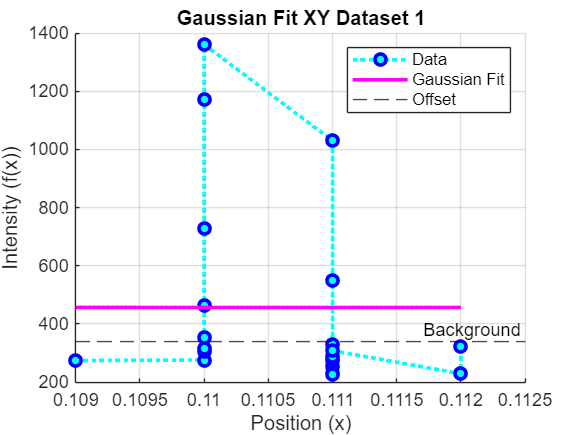

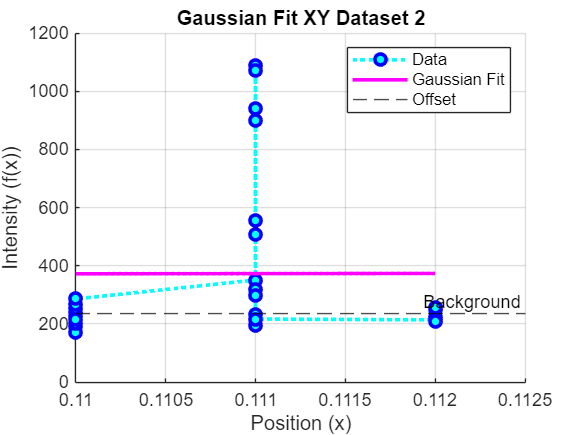

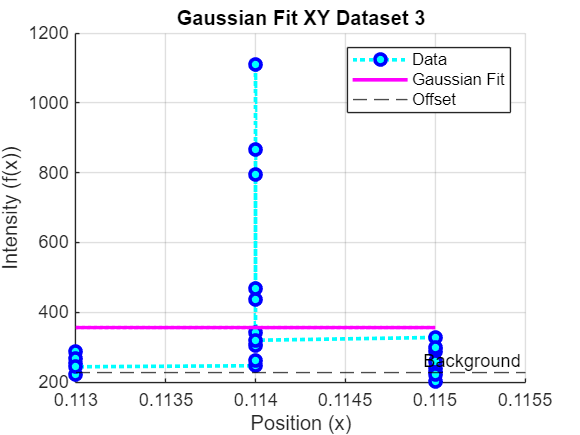

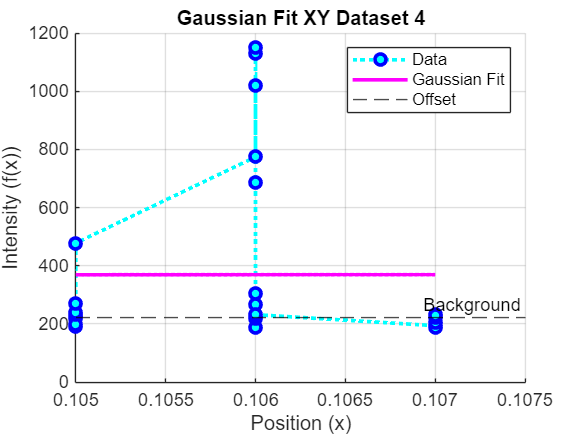

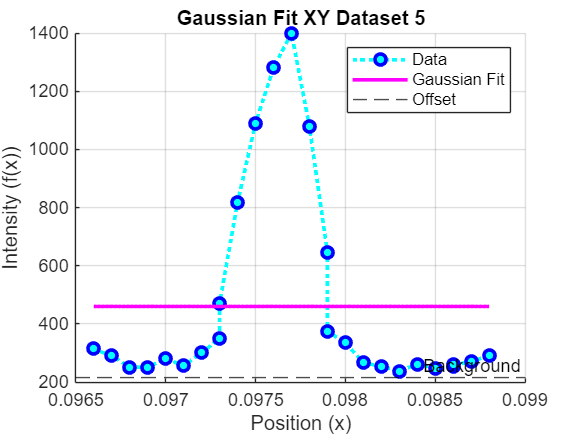

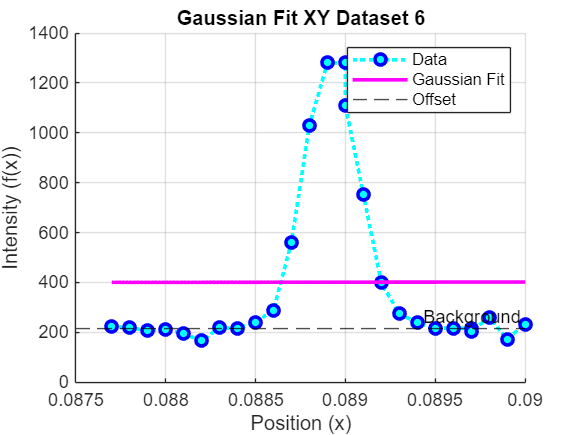

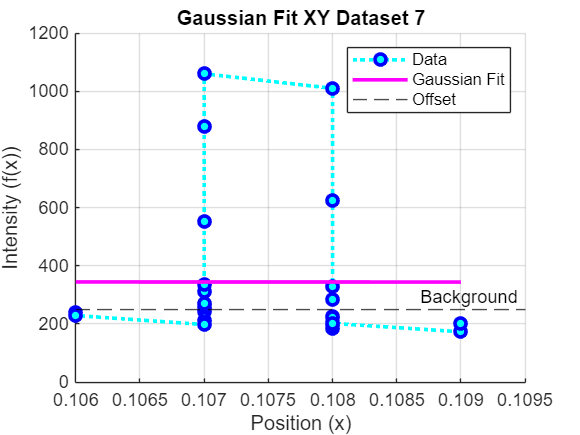

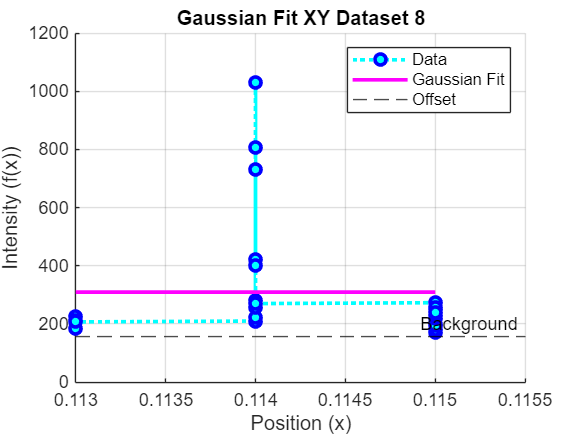

     w0_XY      w0_Z  
    _______    _______

    0.38858     3.7578
    0.13731     0.8076
    0.29567     1.0241
    0.22976     0.6551
    0.30556    0.63211
    0.15741    0.64898
    0.29536    0.65197
    0.37591    0.77871
    0.43687    0.86704
    0.41196    0.65623
     0.2824    0.61067
     0.2429    0.60758
    0.29393    0.66796
    0.29751    0.71414
    0.39311    0.98017



% Confocal Resolution Calculator

% A. Cairns
% 03.18.2025
clc; clear; close all;

%% -----------|| GUI USER INPUT ||-----------
prompt = {'Enter XY file path:', 'Enter Z file path:', 'Enter output folder for figures:', 'Enter excitation wavelength (µm):', 'Enter Numerical Aperture (NA):'};
dlgtitle = 'User Input';
% defaults = {'C:\Users\allis\Downloads\Lateral_day2.xlsx', ...
%             'C:\Users\allis\Downloads\Axial_day2.xlsx', ...
%             'C:\Users\allis\OneDrive - Yale University\Figures', ...
%             '0.488', '1.4'};

defaults = { ...
    'C:\Users\allis\Downloads\Lateral_day2.xlsx', ...
    'C:\Users\allis\Downloads\Axial_day2.xlsx', ...
    'C:\Users\allis\OneDrive - Yale University\Figures', ...
    '0.488', '1.4' ...
};

userInput = inputdlg(prompt, dlgtitle, [1 100], defaults);

XYfileName = userInput{1};
ZfileName = userInput{2};
outputFolder = userInput{3};
lambda = str2double(userInput{4});
NA = str2double(userInput{5});

XYdata = readtable(XYfileName); 
XYdata = XYdata(2:end, :); 
Zdata = readtable(ZfileName); 
Zdata = Zdata(2:end, :);

numColsXY = width(XYdata);
numColsZ = width(Zdata);
numDatasetsXY = numColsXY / 2; 
numDatasetsZ = numColsZ / 2;   
w0sXY = ones(numDatasetsXY, 1);  
w0sZ = ones(numDatasetsZ, 1);


% Line profiles
XYdata = readtable(XYfileName); 
XYdata = XYdata(2:end, :); % skip headers
Zdata = readtable(ZfileName); 
Zdata = Zdata(2:end, :);

% Put this at the very top of your script, before any figure/gca calls:
set(groot, ...
    'defaultAxesFontName',     'Helvetica', ...   % axes tick labels & titles
    'defaultTextFontName',     'Helvetica', ...   % any text()
    'defaultLegendFontName',   'Helvetica', ...   % legend text
    'defaultColorbarFontName', 'Helvetica' ...    % colorbar labels
);

% Preallocate storage for datasets
numColsXY = width(XYdata);
numColsZ = width(Zdata);
numDatasetsXY = numColsXY / 2; % Assuming each dataset has an (x,y) pair
numDatasetsZ = numColsZ / 2;   
w0sXY = ones(numDatasetsXY, 1);  
w0sZ = ones(numDatasetsZ, 1);    

% --- || Loop through each XY dataset ||---
% -----------------------------------------
for i = 1:numDatasetsXY
    % Extract x and y values for XY dataset
    Xcols = 2 * i - 1; % x-values (odd columns)
    Ycols = 2 * i;     % y-values (even columns)

    % Ensure there are no NaN values (for variable row lengths)
    validIdx = ~isnan(XYdata{:, Xcols}) & ~isnan(XYdata{:, Ycols});
    x = XYdata{validIdx, Xcols};
    y = XYdata{validIdx, Ycols};

    % Skip if empty
    if isempty(x) || isempty(y)
        continue;
    end

    % Find the index of the maximum y value
    [~, maxIndex] = max(y);
    x0 = x(maxIndex); % Initial peak location guess

    % ---- || Define the Gaussian function with background || ---
    gaussian = @(params, x) params(1) * exp(-((x - params(2)).^2) / (2 * params(3)^2)) + params(4);

    % Define the error function (sum of squared residuals)
    errorFxn = @(params) sum((gaussian(params, x) - y).^2);

    % Initial parameter guesses [a0, x0, w0, B]
    FWHM_LSM = 0.5;            % µm
    sigmaGuess = FWHM_LSM/2.355;  % ≈0.212 µm
    initGuess = [max(y), x0, sigmaGuess, min(y)];  % w0 = 0.1 (initial)

    % Perform optimization - 100 iterations
    options = optimset('MaxIter', 100, 'Display', 'off');
    optimizedParams = fminsearch(errorFxn, initGuess, options);

    % Extract optimized w0 value for XY
    w0sXY(i) = optimizedParams(3); % Store optimized w0 for XY

    % Generate fitted curve for XY
    Xfit = linspace(min(x), max(x), 300);
    Yfit = gaussian(optimizedParams, Xfit);

    % Plot individual Gaussian fits for XY
    figure;
    hold on;
    % Data
    plot(x, y, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'b', 'LineWidth', 2);
    % Gaussian Fit
    plot(Xfit, Yfit, 'm-', 'LineWidth', 2);
    yline(optimizedParams(4), '--', 'Background', 'Color', 'k');
    % Format
    xlabel('Position (x)');
    ylabel('Intensity (f(x))');
    title(['Gaussian Fit for XY Dataset ', num2str(i)]);
    legend('Data', 'Gaussian Fit', 'Background Level');
    grid on;
    hold off;
end

% ---|| Loop through each Z dataset ||---
% -----------------------------------------
fvalZ = [];
pointsAroundPeak = 30; % number of points to include on each side

for i = 1:numDatasetsZ
    % Extract x and z values for Z dataset
    Xcols = 2 * i - 1; % x-values in odd columns
    Zcols = 2 * i;     % z-values in even columns

    % Ensure there are no NaN values (for variable row lengths)
    validIdx = ~isnan(Zdata{:, Xcols}) & ~isnan(Zdata{:, Zcols});
    xFull = Zdata{validIdx, Xcols};
    zFull = Zdata{validIdx, Zcols};
    
    % Skip if dataset is empty
    if isempty(xFull) || isempty(zFull)
        continue;
    end

    % Find the index of the maximum z value
    [~, maxIndex] = max(zFull);
    
    % Calculate start and end indices for cropping
    startIdx = max(maxIndex - pointsAroundPeak, 1);
    endIdx = min(maxIndex + pointsAroundPeak, length(zFull));
    
    % Crop to ±35 data points around the peak
    x = xFull(startIdx:endIdx);
    z = zFull(startIdx:endIdx);

    % Define the Gaussian function with background
    gaussian = @(params, x) params(1) * exp(-((x - params(2)).^2) / (2 * params(3)^2)) + params(4);

    % Define the error function (sum of squared residuals)
    errorFxn = @(params) sum((gaussian(params, x) - z).^2);

    % Initial parameter guesses [a0, x0, w0, B]
    initGuess = [max(z), x(maxIndex - startIdx + 1), 0.5, min(z)];  % Correct x0 using cropped indexing

    % Perform optimization
    options = optimset('MaxIter', 100, 'Display', 'off');
    [optimizedParams, fval] = fminsearch(errorFxn, initGuess, options);
    fvalZ(i) = fval;
    
    % Extract optimized w0 value for Z
    w0sZ(i) = optimizedParams(3); % Store optimized w0 for Z

    % Generate fitted curve for Z
    Xfit = linspace(min(x), max(x), 300);
    Zfit = gaussian(optimizedParams, Xfit);

    % Plot individual Gaussian fits for Z
    figure;
    hold on;
    % Data
    plot(x, z, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'b', 'LineWidth', 2);
    % Gaussian Fit
    plot(Xfit, Zfit, 'g-', 'LineWidth', 2);
    yline(optimizedParams(4), '--', 'Background', 'Color', 'k');
    % Format
    xlabel('Position (x)');
    ylabel('Intensity (f(x))');
    title(['Gaussian Fit for Z Dataset ', num2str(i)]);
    legend('Data', 'Gaussian Fit', 'Background Level');
    grid on;
    hold off;
end


% % %% w0 Table - only works if XY & Z have the same number of datapoints
% % % Combine and display results for XY and Z datasets
% % w0s_all = zeros(50,2);  % Combine XY and Z results
% % w0s_all(:,1) = w0sXY;
% % w0s_all(:,2) = w0sZ;

% Convert results to a table
w0_table = array2table(w0s_all, 'VariableNames', {'w0_{XY}','w0_{Z}'} );

% Display the table
disp('Optimized w0 values for XY and Z:');
disp(w0_table);

% ---|| Calculate FWHM for XY ||---
% -----------------------------------------

% Plot histogram of optimized w0 values for XY
figure;
histogram(w0sXY, 'FaceColor', 'm', 'EdgeColor', 'k');
xlabel('Optimized w0 (µm) for XY', 'FontName', 'Helvetica', 'FontSize', 7);
ylabel('Frequency', 'FontName', 'Helvetica', 'FontSize', 7);
title('Distribution of Optimized w0 Values for XY');
grid on;

FWHMs_XY = 2.355 * w0sXY;

% Plot histogram of FWHM values for XY
figure;
% histogram(FWHMs_XY, 'FaceColor', [0, 0.3, 0.9], 'EdgeColor', 'k', 'LineWidth', 0.75);
histogram(FWHMs_XY, 'NumBins', 6,'FaceColor', 'c', 'EdgeColor', 'k', 'LineWidth', 0.75);
xlabel('FWHM for XY (µm)', 'FontName', 'Helvetica', 'FontSize', 7);
ylabel('Frequency', 'FontName', 'Helvetica', 'FontSize', 7);
set(gca, 'FontName', 'Helvetica', 'FontSize', 7, 'LineWidth', 0.75);
box on;
% title('Distribution of FWHM Values for XY');

% Format
figWidth  = 9;    % inches (adjust as needed)
figHeight = 6;    % inches
set(gcf, ...
    'Units',      'inches', ...
    'Position',   [1 1 figWidth figHeight], ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0 0 figWidth figHeight] ...
);

% 2) Use Nature‑style fonts and large sizes:
set(gca, ...
    'FontName', 'Helvetica', ...
    'FontSize', 20, ...      % tick labels
    'LabelFontSizeMultiplier', 1.4 ...  % makes axis labels ~17 pt
);

fprintf('Number of Z‑profiles fitted: %d\n', numel(w0sXY));

fprintf('Number of Z‑profiles fitted: %d\n', numel(w0sZ));


saveas(gcf, fullfile(outputFolder, 'FWHMlateral.png'));
print(gcf, fullfile(outputFolder, 'FWHMlateral'), '-dpng', '-r600');
% For Adobe Illustrator
print(gcf, fullfile(outputFolder, 'FWHMlateral'), '-depsc', '-r600');


%% Theoretical Values
% Compute theoretical lateral resolution (XY) 
XYresPan = 0.61 * lambda / NA;

% Compute mean and standard deviation of FWHM for XY
meanFWHM_XY = mean(FWHMs_XY);
stdFWHM_XY = std(FWHMs_XY);

% Compute ratio of FWHM to theoretical lateral resolution (XY)
ratioXY = meanFWHM_XY / XYresPan;

% Display comparison for XY
fprintf('Theoretical Lateral Resolution (XY) for pan ch.: %.4f µm\n', XYresPan);
fprintf('Mean Experimental FWHM for XY: %.4f µm\n', meanFWHM_XY);
fprintf('Standard Deviation of FWHM for XY: %.4f µm\n', stdFWHM_XY);
fprintf('Ratio (FWHM / Theoretical XY Resolution for pan ch.): %.2f\n', ratioXY);

% Perform a one-sample t-test for XY comparing to theoretical resolution
[h_XY, p_XY] = ttest(FWHMs_XY, XYresPan);

% Display test results for XY
if h_XY == 0
    fprintf('No significant difference for XY (p = %.4f)\n', p_XY);
else
    fprintf('Significant difference for XY (p = %.4f)\n', p_XY);
end

% --- || Calculate FWHM for Z ||---
% -----------------------------------------

% Plot histogram of optimized w0 values for Z
figure;
histogram(w0sZ, 'FaceColor', 'g', 'EdgeColor', 'k');
xlabel('Optimized w0 (µm) for Z');
ylabel('Frequency');
title('Distribution of Optimized w0 Values for Z');
ylim([0 20]);
grid on;

FWHMs_Z = 2.355 * w0sZ;

% Plot histogram of FWHM
figure;
% histogram(FWHMs_Z, 'FaceColor', [0, 0.3, 0.9], 'EdgeColor', 'k');
histogram(FWHMs_Z, 'NumBins', 6,'FaceColor', 'b', 'EdgeColor', 'k');
xlabel('FWHM for Z (µm)', 'FontName', 'Helvetica', 'FontSize', 7);
ylabel('Frequency', 'FontName', 'Helvetica', 'FontSize', 7);
ylim([0 20]);
set(gca, 'FontName', 'Helvetica', 'FontSize', 7, 'LineWidth', 0.75);
box on;
% title('Distribution of FWHM Values for Z');


% Compute theoretical axial resolution (Z) for pan channel
ZresPan = 2 * lambda / (NA^2);

% Compute mean and standard deviation of FWHM for Z
meanFWHM_Z = mean(FWHMs_Z);
stdFWHM_Z = std(FWHMs_Z);

% Compute ratio of FWHM to theoretical axial resolution (Z)
ratioZ = meanFWHM_Z / ZresPan;

% Display comparison for Z
fprintf('Theoretical Axial Resolution (Z) for pan ch.: %.4f µm\n', ZresPan);
fprintf('Mean Experimental FWHM for Z: %.4f µm\n', meanFWHM_Z);
fprintf('Standard Deviation of FWHM for Z: %.4f µm\n', stdFWHM_Z);
fprintf('Ratio (FWHM / Theoretical Z Resolution for pan ch.): %.2f\n', ratioZ);

% Perform a one-sample t-test for Z comparing to theoretical resolution
[h_Z, p_Z] = ttest(FWHMs_Z, ZresPan);

% Display test results for Z
if h_Z == 0
    fprintf('No significant difference for Z (p = %.4f)\n', p_Z);
else
    fprintf('Significant difference for Z (p = %.4f)\n', p_Z);
end

% Format
figWidth  = 9;    % inches (adjust as needed)
figHeight = 6;    % inches
set(gcf, ...
    'Units',      'inches', ...
    'Position',   [1 1 figWidth figHeight], ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0 0 figWidth figHeight] ...
);

% 2) Use Nature‑style fonts and large sizes:
set(gca, ...
    'FontName', 'Helvetica', ...
    'FontSize', 20, ...      % tick labels
    'LabelFontSizeMultiplier', 1.4 ...  % makes axis labels ~17 pt
);

saveas(gcf, fullfile(outputFolder, 'FWHMaxial.png'));
print(gcf, fullfile(outputFolder, 'FWHMaxial'), '-dpng', '-r600');
% For Adobe Illustrator
print(gcf, fullfile(outputFolder, 'FWHMaxial'), '-depsc', '-r600');

%% Bar Plot Comparison of Theoretical and Experimental Resolution

figure;

% Set up the data for plotting (XY and Z)
labels = {'XY', 'Z'};
theoretical_res = [XYresPan, ZresPan];
mean_FWHM = [meanFWHM_XY, meanFWHM_Z];  
std_FWHM = [stdFWHM_XY, stdFWHM_Z];  

% Define the positions for the bars to avoid overlap
xPos = 1:length(labels);  % Positions for the categories
barWidth = 0.3;
hold on;

% Plot bars for Theoretical Resolution
barTheor = bar(xPos - barWidth / 2, theoretical_res, barWidth, 'FaceColor', [0.8, 0.8, 0.8], 'EdgeColor', 'k');

% Plot bars for Mean Experimental FWHM
barExp = bar(xPos + barWidth / 2, mean_FWHM, barWidth, 'FaceColor', [0, 0.5, 1], 'EdgeColor', 'k');
% Plot error bars (standard deviation) for Experimental FWHM
errorbar(xPos + barWidth / 2, mean_FWHM, std_FWHM, 'k', 'LineStyle', 'none', 'LineWidth', 2, 'CapSize', 10);

% Format
set(gca, 'XTick', xPos, 'XTickLabel', labels);
xlabel('Lateral/ Axial Resolution');
ylabel('Resolution (µm)');
ylim([0, 1.5*stdFWHM_Z+ meanFWHM_Z])
title('Comparison of Theoretical and Experimental Resolution');
legend([barTheor, barExp], 'Theoretical Resolution', 'Mean Experimental FWHM', 'Location', 'Southeast');
grid on;

% Display values on top of the bars
for i = 1:length(xPos) % For Theoretical Resolution
    text(xPos(i) - barWidth / 2, theoretical_res(i) + 0.02, sprintf('%.4f', theoretical_res(i)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10);
end

for i = 1:length(xPos) % For SD (error bars)
    text(xPos(i) + barWidth / 2, mean_FWHM(i) + std_FWHM(i) + 0.02, sprintf('%.4f ± %.4f', mean_FWHM(i), std_FWHM(i)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10);
end

hold off;

%% Bar Plot of Experimental Resolution

figure;
% Set up the data for plotting (XY and Z)
labels = {'XY', 'Z'};
mean_FWHM = [meanFWHM_XY, meanFWHM_Z]; 
std_FWHM = [stdFWHM_XY, stdFWHM_Z];  

% Define the positions for the bars to avoid overlap
xPos = 1:length(labels);  % Positions for the categories

barWidth = 0.3;
hold on;

% Plot bars for Mean FWHM
barExp = bar(xPos + barWidth / 2, mean_FWHM, barWidth, 'FaceColor', [0, 0.5, 1], 'EdgeColor', 'k');
% Plot error bars (standard deviation) for FWHM
errorbar(xPos + barWidth / 2, mean_FWHM, std_FWHM, 'k', 'LineStyle', 'none', 'LineWidth', 1, 'CapSize', 4);

% Format
set(gca, 'XTick', xPos, 'XTickLabel', labels);
xlabel('Mean Experimental FWHM', 'FontName', 'Helvetica', 'FontSize', 7);
ylabel('Resolution (µm)', 'FontName', 'Helvetica', 'FontSize', 7);
ylim([0, 1.5*stdFWHM_Z+ meanFWHM_Z])
set(gca, 'XTick', xPos, 'XTickLabel', labels, 'FontName', 'Helvetica', 'FontSize', 7, 'LineWidth', 0.75);
box on;
% title('Lateral and Axial Experimental Resolution');


% SD (error bars) text on plot
for i = 1:length(xPos) 
    text(xPos(i) + barWidth / 2, mean_FWHM(i) + std_FWHM(i) + 0.02, sprintf('%.4f ± %.4f', mean_FWHM(i), std_FWHM(i)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontName', 'Helvetica', 'FontSize', 7);
end
hold off;

saveas(gcf, fullfile(outputFolder, 'LateralAxialRes.png'));
print(gcf, fullfile(outputFolder, 'LateralAxialRes'), '-dpng', '-r600');
